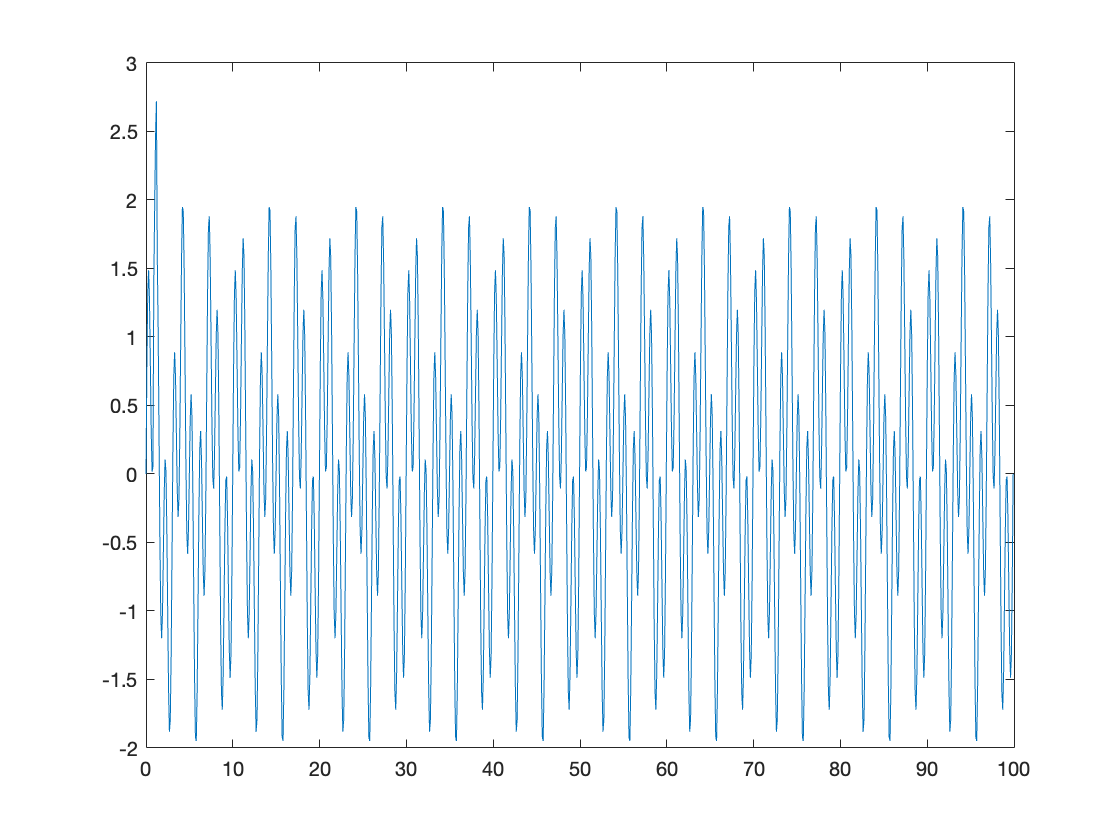

fs=100;
t=0:1/fs:10; % time vector
s1=sin(2*pi*10*t) + sin(2*pi*3*t); %signal
s1(10:13) = s1(10:13) + 1;
omega=linspace(0,fs,length(t)+1);omega(end)=[]; % generate vector of frequencies
figure;plot(omega,s1);

addpath ./SSD/

components = SSD(s1,fs)

components =     0.3585    0.7920    0.9460    0.7460    0.2463   -0.3784   -0.8911   -1.0839   -0.8652   -0.3044    0.3899    0.9528    1.1696    0.9607    0.4092   -0.2783   -0.8534   -1.1170   -0.9867   -0.5192    0.1147    0.6919    1.0122    0.9666    0.5745   -0.0214   -0.6033   -0.9564   -0.9493   -0.5839    0.0025    0.5879    0.9495    0.9489    0.5860   -0.0010   -0.5880   -0.9509   -0.9510   -0.5884   -0.0015    0.5855    0.9484    0.9486    0.5862   -0.0003   -0.5869   -0.9494   -0.9491   -0.5862
    0.0501    0.2557    0.4527    0.6340    0.7936    0.9262    1.0278    1.0950    1.1256    1.1181    1.0724    0.9895    0.8715    0.7226    0.5480    0.3543    0.1487   -0.0611   -0.2673   -0.4630   -0.6416   -0.7973   -0.9252   -1.0211   -1.0815   -1.1042   -1.0878   -1.0326   -0.9406   -0.8150   -0.6609   -0.4844   -0.2922   -0.0916    0.1104    0.3069    0.4914    0.6578    0.8008    0.9152    0.9970    1.0428    1.0507    1.0205    0.9534    0.8523    0.7213    0.5658    0.

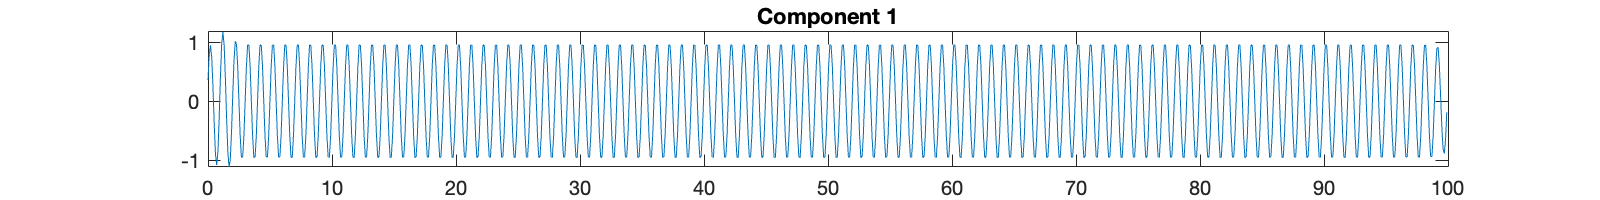

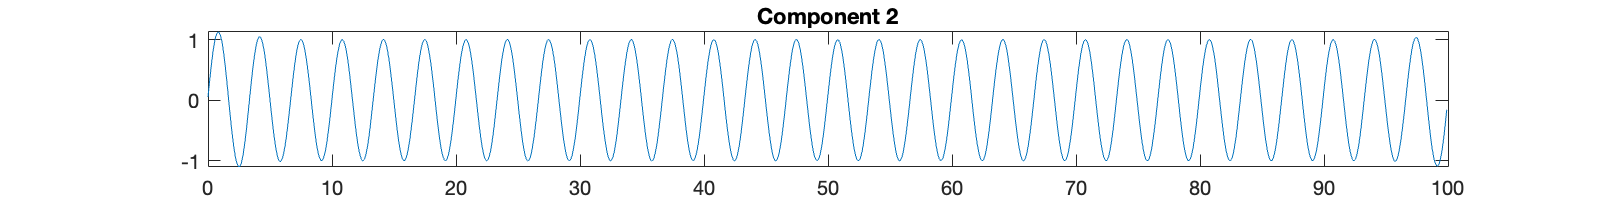

addpath ./plotting/

plot_SSD_components(omega, components)

load("data/data-20130307T015746Z.mat")
vibration

vibration =    -0.4146
    0.1725
   -0.4038
   -0.7735
    0.6866
    3.3392
    3.6856
    1.9115
    2.0076
    1.6358


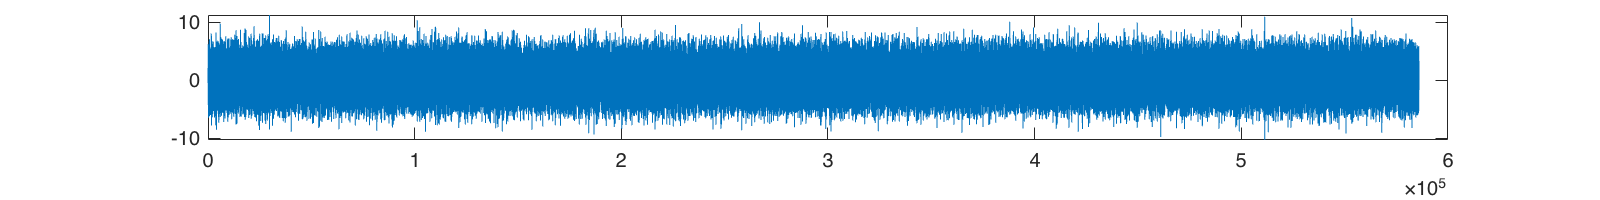

plot(vibration)


fs = 1 / size(vibration, 1)

fs = 1.7067e-06

t = linspace(0 , 6, size(vibration, 1))

t =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005


% Get file names
fname = dir('./data');
fname = {fname.name};
fname = fname(3:end);

% Initialize empty cell array to store data
df = [];

% Loop through file names and load data
for i = 1:length(fname)
    data = load(['./data/', fname{i}]);
    df = [df; data.vibration(:)'];
end

% Calculate scan frequency
fs = fix(size(df, 2) / 6);

% Create time vector
t = linspace(0, 6, size(df, 2));

omega=linspace(0,fs,length(t)+1);omega(end)=[]; % generate vector of frequencies

% Display scan frequency
fprintf('Scan frequency: %d Hz\n', fs);

Scan frequency: 97656 Hz


components = SSD(df(1, :), fs)

components =    -0.0441    0.0430   -0.0359    0.0249   -0.0124    0.0010    0.0072   -0.0104    0.0081   -0.0007   -0.0103    0.0228   -0.0343    0.0424   -0.0448    0.0402   -0.0282    0.0094    0.0148   -0.0416    0.0682   -0.0912    0.1077   -0.1153    0.1123   -0.0982    0.0733   -0.0394   -0.0009    0.0442   -0.0868    0.1248   -0.1546    0.1733   -0.1785    0.1693   -0.1455    0.1085   -0.0606    0.0053    0.0533   -0.1107    0.1623   -0.2037    0.2313   -0.2425    0.2358   -0.2115    0.1710   -0.1174
   -0.0292    0.0148    0.0059   -0.0276    0.0442   -0.0505    0.0439   -0.0253   -0.0012    0.0288   -0.0504    0.0600   -0.0547    0.0353   -0.0065   -0.0244    0.0497   -0.0627    0.0602   -0.0427    0.0147    0.0166   -0.0435    0.0591   -0.0598    0.0459   -0.0211   -0.0079    0.0338   -0.0503    0.0537   -0.0439    0.0241    0.0002   -0.0225    0.0376   -0.0423    0.0365   -0.0226    0.0051    0.0113   -0.0226    0.0268   -0.0241    0.0165   -0.0070   -0.0014    0.0068   -0.

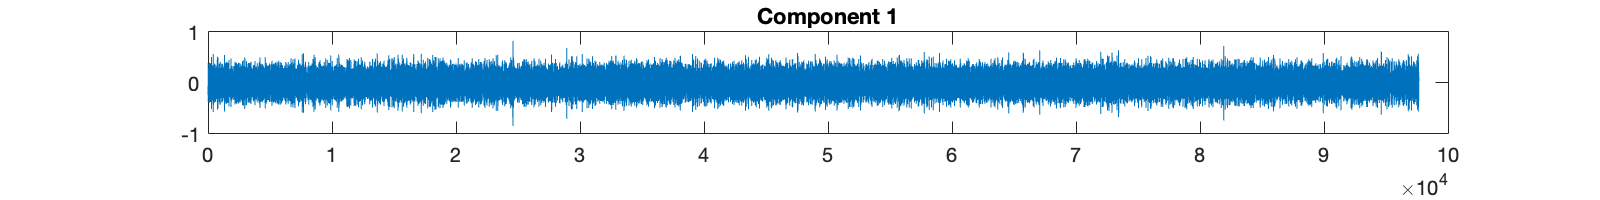

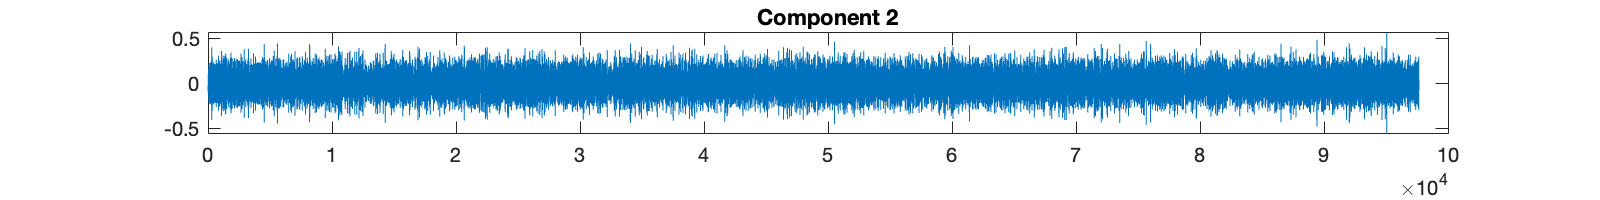

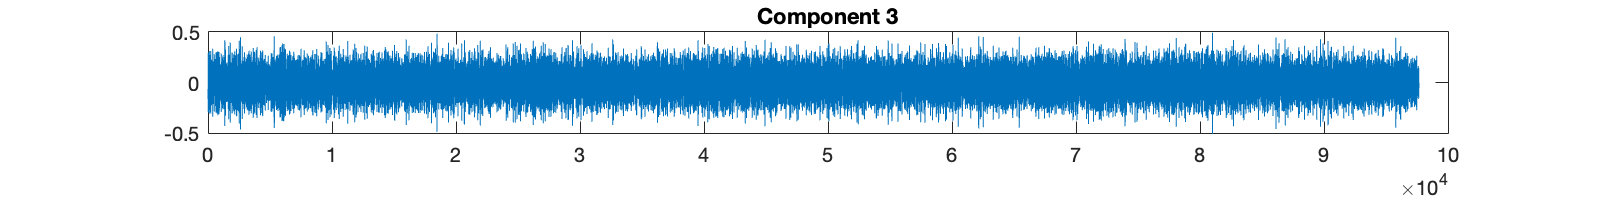

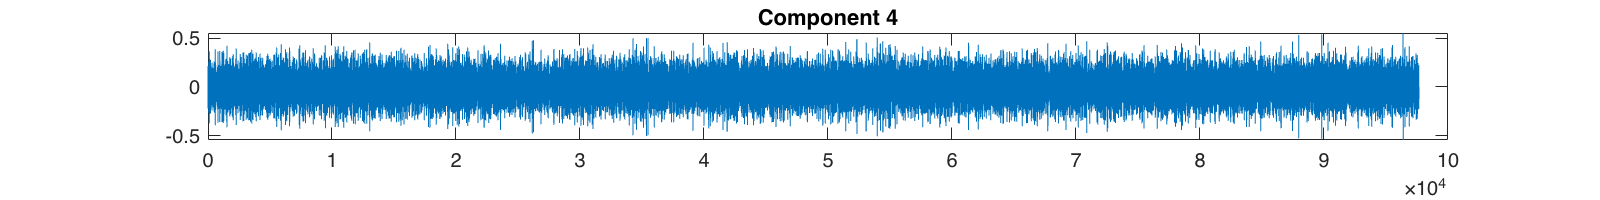

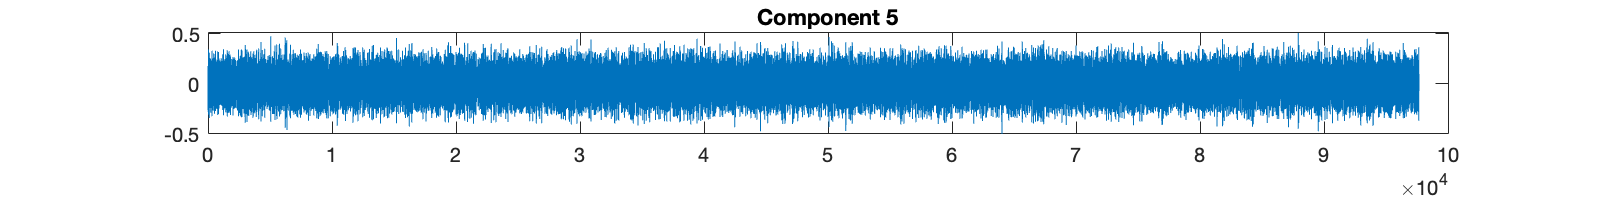

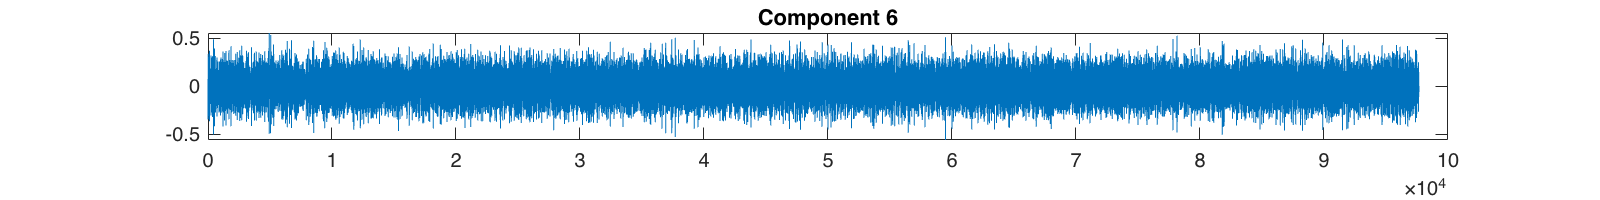

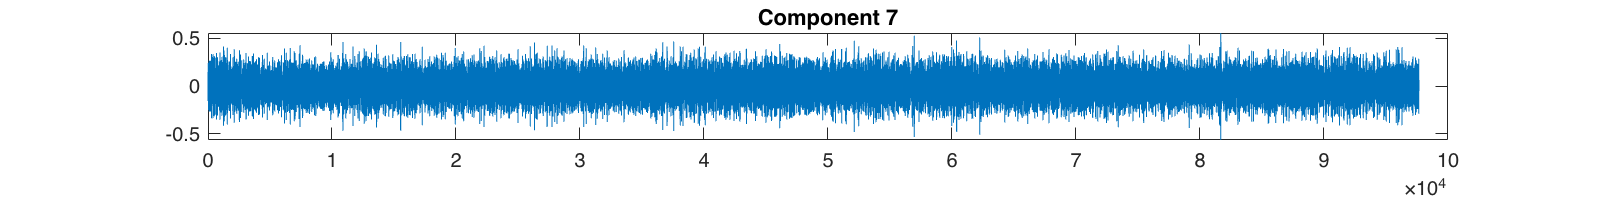

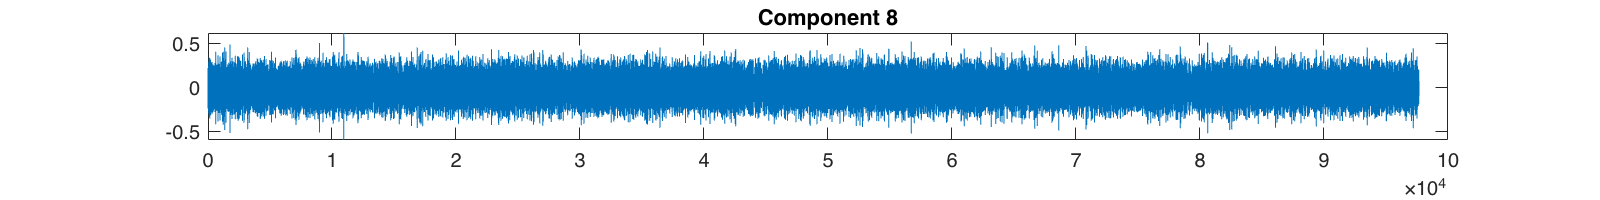

plot_SSD_components(omega, components)

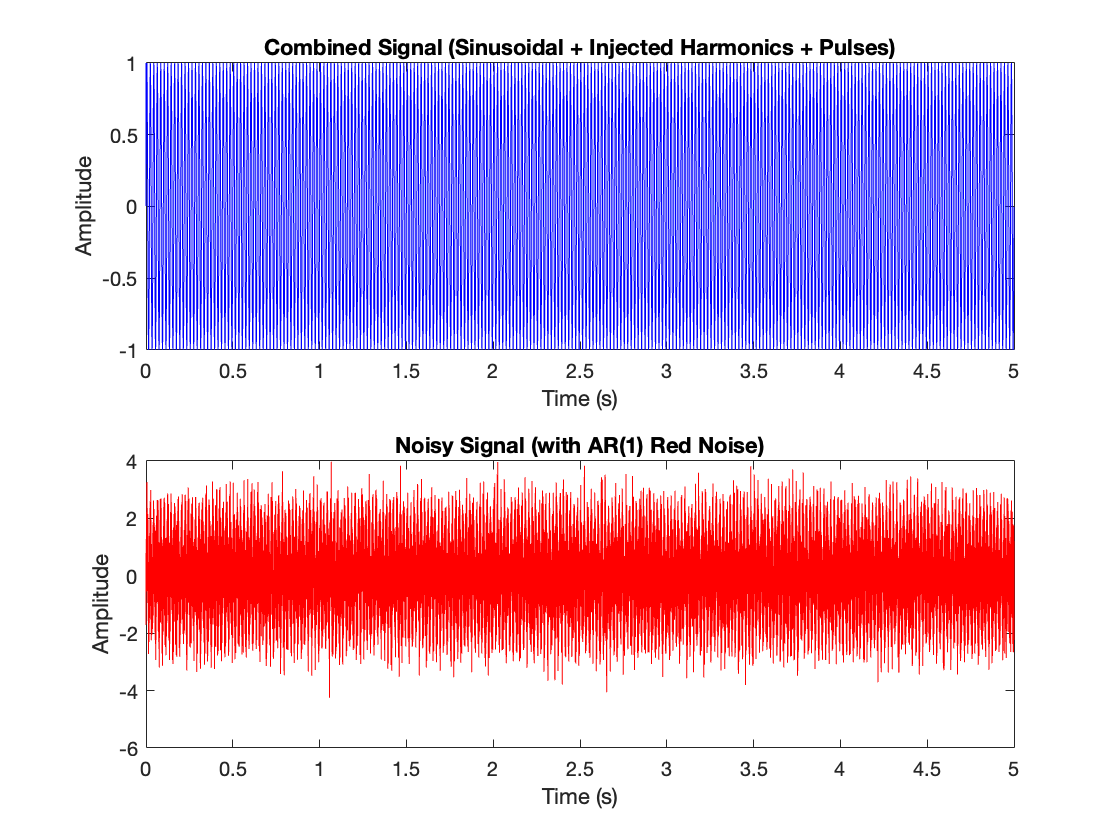

% Parameters
fs = 100000; % Sampling frequency (Hz)
t = 0:1/fs:5-1/fs; % Time vector for 5 seconds
f_sinusoidal = 50; % Frequency of the sinusoidal signal (Hz)
f_injected_harmonic = 2*f_sinusoidal; % Frequency of the injected harmonic (2nd harmonic)
f_pulse = 180; % Frequency of the pulses (Hz)
pulse_duration = 10e-6; % Duration of the pulses (s)

% Generate sinusoidal signal
sinusoidal_signal = sin(2*pi*f_sinusoidal*t);

% Inject small signals
sinusoidal_signal(100:199) = sinusoidal_signal(100:199) + 0.2*sin(2*pi*f_injected_harmonic*t(100:199));
sinusoidal_signal(400:499) = sinusoidal_signal(400:499) + 0.1*sin(2*pi*2*f_sinusoidal*t(400:499)) + 0.05*sin(2*pi*3*f_sinusoidal*t(400:499));

% Generate pulses starting from sample 500
pulse_signal = pulstran(t, [0, 5], 'rectpuls', pulse_duration);

% Combine signals
combined_signal = sinusoidal_signal + pulse_signal;

% Generate AR(1) red noise
AR_order = 1;
noise_variance = 0.1; % Adjust as needed
red_noise = filter(1, [1, -0.9], sqrt(noise_variance)*randn(size(t)));

% Add noise to the combined signal
noisy_signal = combined_signal + red_noise;

% Plot the generated signal
figure;
subplot(2,1,1);
plot(t, combined_signal, 'b');
title('Combined Signal (Sinusoidal + Injected Harmonics + Pulses)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, noisy_signal, 'r');
title('Noisy Signal (with AR(1) Red Noise)');
xlabel('Time (s)');
ylabel('Amplitude');

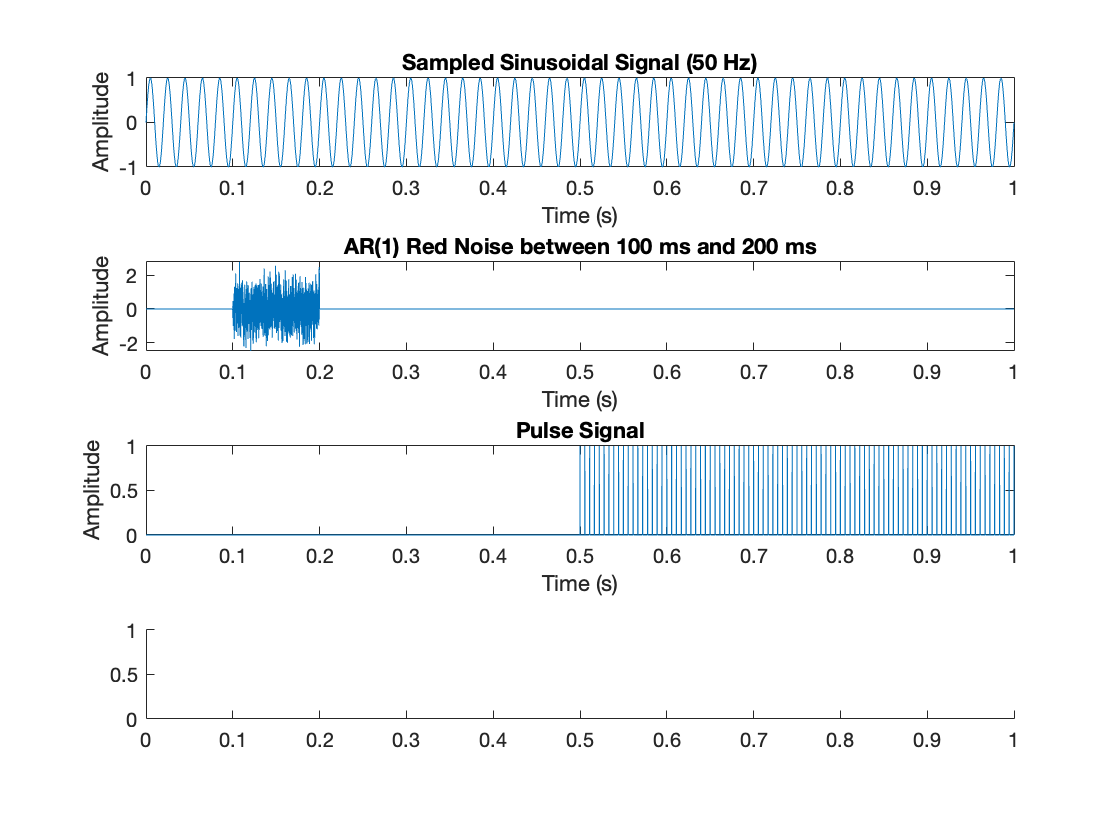

% Parameters
fs = 100000; % Sampling frequency (Hz)
t = 0:1/fs:1; % Time vector for 1000 milliseconds
f_sinusoidal = 50; % Frequency of the sinusoidal signal (Hz)

% Generate sinusoidal signal
sinusoidal_signal = sin(2*pi*f_sinusoidal*t);

% Generate AR(1) red noise
AR_order = 1;
noise_variance = 0.1; % Adjust as needed

% Generate white noise
white_noise = sqrt(noise_variance)*randn(size(t));

% Generate AR(1) red noise using filter
red_noise = filter(1, [1, -0.9], white_noise);

% Add chirp of the 2nd harmonic between samples 100 and 200
chirp_start = 100;
chirp_end = 200;
f_start = 2; % Starting frequency of chirp (2nd harmonic)
f_end = 10; % Ending frequency of chirp (2nd harmonic)
chirp_signal = chirp(t(chirp_start:chirp_end), f_start, 1, f_end);

% Combine red noise with chirp signal
red_noise_1(chirp_start:chirp_end) = red_noise(chirp_start:chirp_end) + chirp_signal;
red_noise_1(t < 0.1) = 0;
red_noise_1(t > 0.2) = 0;

% Add sequence of pulses of 10 μs at 180 Hz between samples 500 and 1,000
pulse_duration = 10e-6; % Duration of the pulses (s)
pulse_frequency = 180; % Frequency of the pulses (Hz)
pulse_signal = pulstran(t, 0.5:1/pulse_frequency:1, 'rectpuls', pulse_duration);

% Add chirp of the 2nd and 3rd harmonics between samples 400 and 500
chirp_start = 400;
chirp_end = 500;
f_start_2nd = 2*50; % Starting frequency of chirp (2nd harmonic)
f_end_2nd = 10*50; % Ending frequency of chirp (2nd harmonic)
f_start_3rd = 3*50; % Starting frequency of chirp (3rd harmonic)
f_end_3rd = 15*50; % Ending frequency of chirp (3rd harmonic)
chirp_2nd = chirp(t(chirp_start:chirp_end), f_start_2nd, 1, f_end_2nd);
chirp_3rd = chirp(t(chirp_start:chirp_end), f_start_3rd, 1, f_end_3rd);

% Plot the sampled sinusoidal signal
figure;
subplot(4,1,1);
plot(t, sinusoidal_signal);
title('Sampled Sinusoidal Signal (50 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot red noise
subplot(4,1,2);
plot(t, red_noise);
title('AR(1) Red Noise between 100 ms and 200 ms');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot impulses
subplot(4,1,3);
plot(t, pulse_signal);
title('Pulse Signal');
xlabel('Time (s)');
ylabel('Amplitude');
% Plot red noise
subplot(4,1,4);

plot(t, chirp_3rd);

Error using plot
Vectors must be the same length.

title('AR(1) Red Noise between 100 ms and 200 ms');
xlabel('Time (s)');
ylabel('Amplitude');

% Parameters
fs = 100000; % Sampling frequency (Hz)
t = 0:1/fs:1-1/fs; % Time vector for 5 seconds
block_size = 100; % Block size for averaging
num_blocks = length(t) / block_size;

% Generate 50 Hz sinusoidal signal
sinusoidal_signal = sin(2*pi*50*t);

% Generate AR(1) red noise
AR_order = 1;
noise_variance = 1; % Adjust as needed
red_noise = filter(1, [1, -0.9], sqrt(noise_variance)*randn(size(t)));

% Add chirp of the 2nd harmonic between samples 100 and 200
chirp_start_1 = 100;
chirp_end_1 = 200;
f_start_1 = 2; % Starting frequency of chirp (2nd harmonic)
f_end_1 = 10; % Ending frequency of chirp (2nd harmonic)
chirp_signal_1 = chirp(t(chirp_start_1:chirp_end_1), f_start_1, 1, f_end_1);

% Combine red noise with chirp signal
red_noise_1(chirp_start_1:chirp_end_1) = red_noise(chirp_start_1:chirp_end_1) + chirp_signal_1;
red_noise_1(t < 0.1) = 0;
red_noise_1(t > 0.2) = 0;

% Add chirp of the 2nd harmonic between samples 100 and 200
chirp_start_2 = 400;
chirp_end_2 = 500;
f_start_2 = 3; % Starting frequency of chirp (2nd harmonic)
f_end_2 = 10; % Ending frequency of chirp (2nd harmonic)
chirp_signal_2 = chirp(t(chirp_start_2:chirp_end_2), f_start_2, 1, f_end_2);
% Combine red noise with chirp signal
red_noise_2(chirp_start_2:chirp_end_2) = red_noise(chirp_start_2:chirp_end_2) + chirp_signal_2;
red_noise_2(t < 0.4) = 0;
red_noise_2(t > 0.5) = 0;

% Add sequence of pulses of 10 μs at 180 Hz between samples 500 and 1,000
pulse_duration = 10e-6; % Duration of the pulses (s)
pulse_frequency = 180; % Frequency of the pulses (Hz)
pulse_signal = pulstran(t, 0.5:1/pulse_frequency:1, 'rectpuls', pulse_duration);


% Combine signals
combined_signal = sinusoidal_signal + red_noise_1 + red_noise_2;

% Average the signal in blocks of 100 samples
averaged_signal = zeros(1, length(t));
for i = 1:num_blocks
    block_start = (i-1)*block_size + 1;
    block_end = i*block_size;
    averaged_signal(block_start:block_end) = mean(combined_signal(block_start:block_end));
end

% Plot the signals
figure;

subplot(3,1,1);
plot(t, combined_signal, 'b');
title('Combined Signal (Sinusoidal + Red Noise + Pulses)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, averaged_signal, 'k');
title('Averaged Signal (Solid Black)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, pulse_signal, 'r');
title('Pulse Signal (Red)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

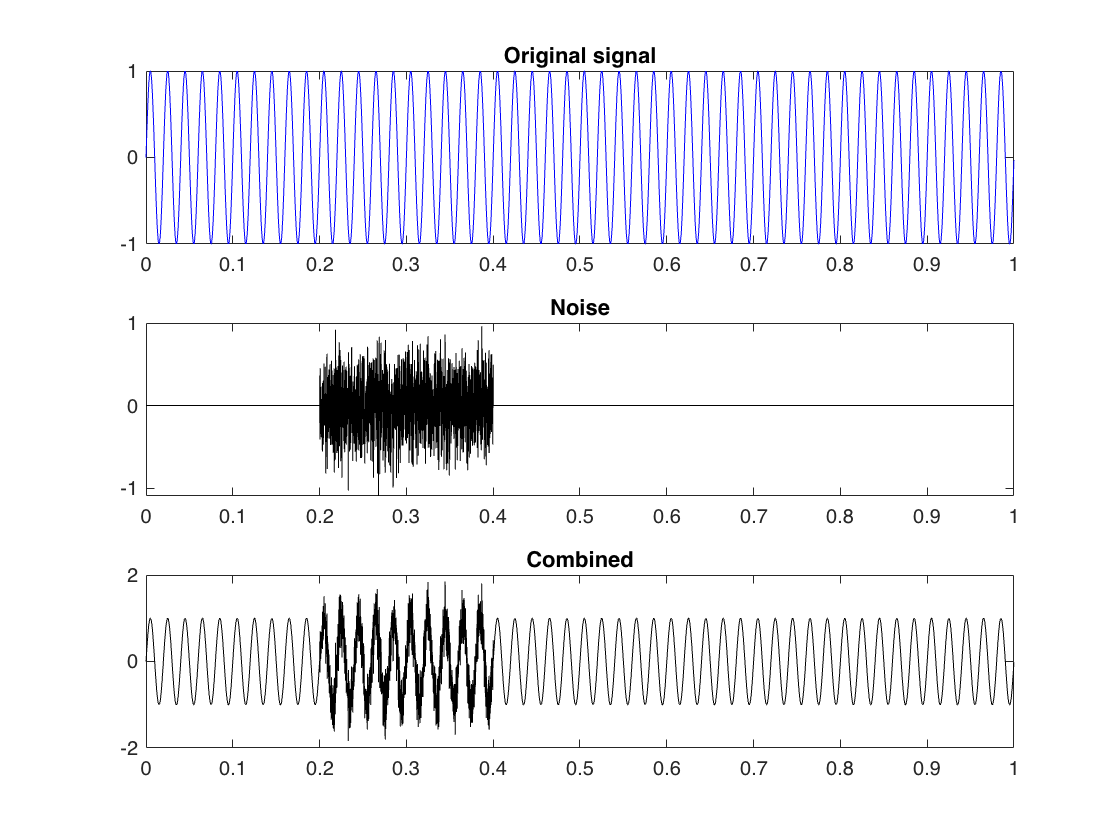

% Parameters
fs = 10000; % Sampling frequency (Hz)
t = 0:1/fs:1-1/fs; % Time vector for 5 seconds
block_size = 100; % Block size for averaging
num_blocks = length(t) / block_size;

% Generate 50 Hz sinusoidal signal
sinusoidal_signal = sin(2*pi*50*t);

% Generate AR(1) red noise
AR_order = 1;
noise_variance = 0.1; % Adjust as needed
red_noise = filter(1, [1, -0.2], sqrt(noise_variance)*randn(size(t)));
red_noise(t < 0.2) = 0;
red_noise(t > 0.4) = 0;

combined_signal = sinusoidal_signal + red_noise;

% Plot the signals
figure;

subplot(3,1,1);
plot(t, sinusoidal_signal, 'b');
title('Original signal');

subplot(3,1,2);
plot(t, red_noise, 'k');
title('Noise');

subplot(3,1,3);
plot(t, combined_signal, 'k');
title('Combined');

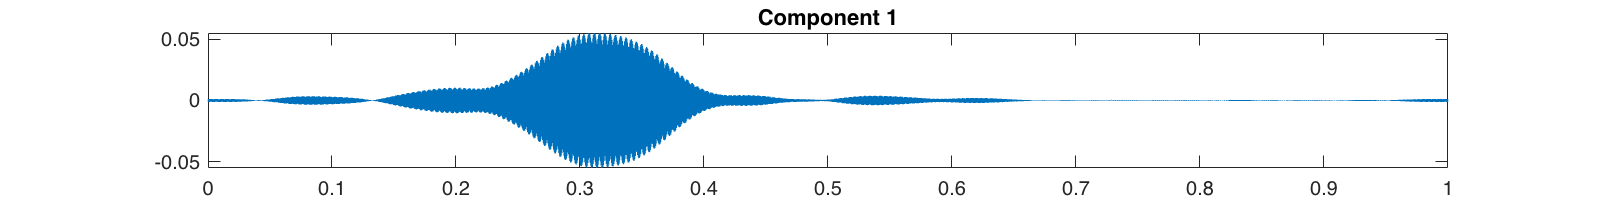

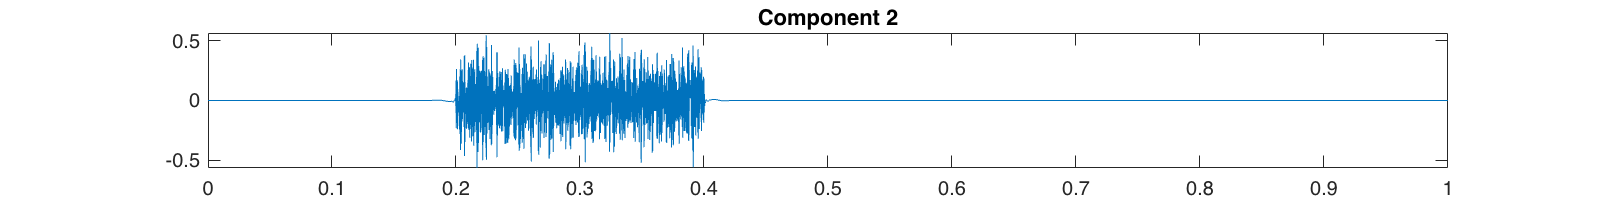

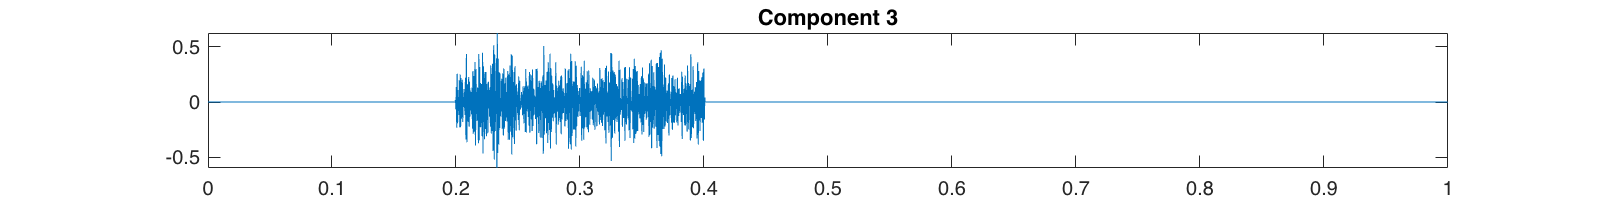

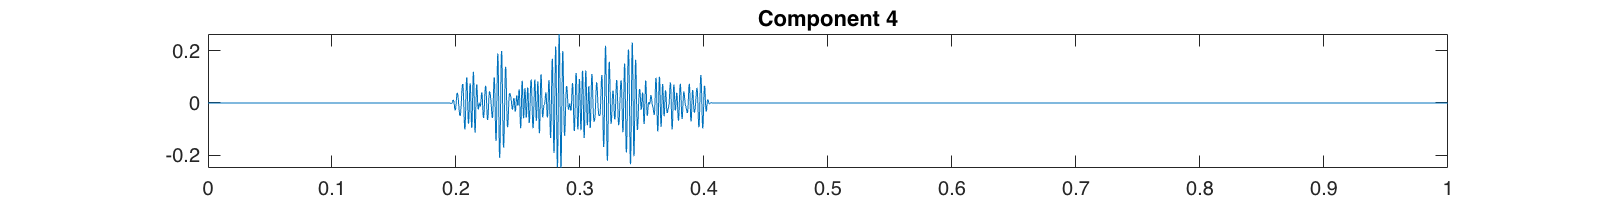

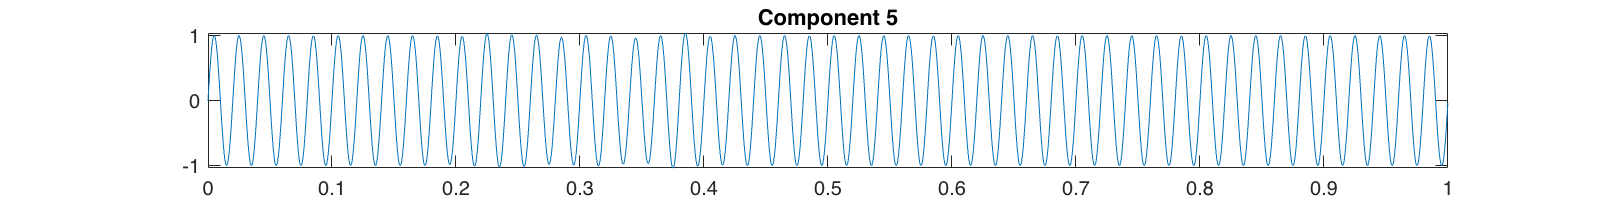

addpath ./SSD/
ssd_components = SSD(combined_signal, fs);
addpath ./plotting/
plot_SSD_components(t,ssd_components)